# The Fate of the American Worker

# srGBM

Set parameters

clear;
mu = 1; 
sigma = 1; 
Xzero = 1; % problem parameters
dt = 0.001;
Xthresh = 2; %threshold for function to stop
X0 = Xzero;
r = 10;
n = 10000;

Simulate income path using srGBM and plot

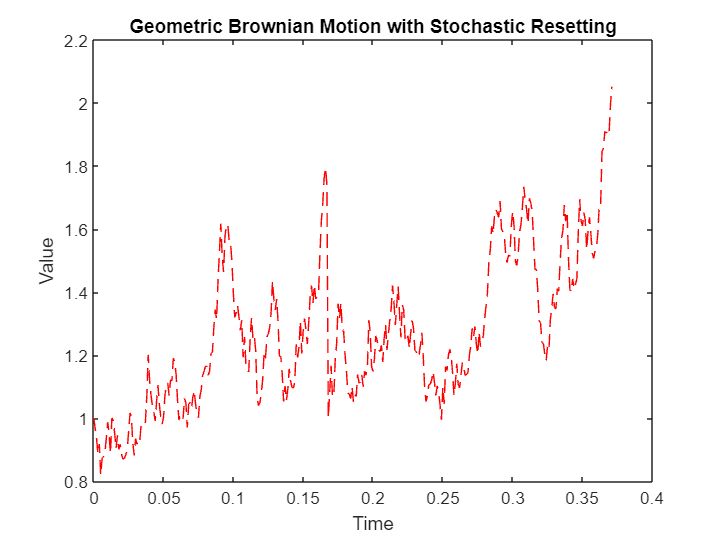

clear g;
% Simulate income path
Xtemp = Xzero;
i = 1;
pz = r*dt;

% preallocate array
g = zeros(2,16);
g(:,1) = [0 Xzero];
while Xtemp < Xthresh
    Z = pz >= rand;
    dW = sqrt(2*dt)*randn;
    Xtemp = Xtemp + (1-Z)*Xtemp*(mu*dt+sigma*dW)+Z*(Xzero-Xtemp);
    
    i = i+1;
    g(:,i) = [i*dt Xtemp]';
    if size(g(1,:)) == i
       %resize array
       g = [g,zeros(2,i)]; 
    end
end


plot(g(1,:),g(2,:),'--r')
hold on

title("Geometric Brownian Motion with Stochastic Resetting") 
xlabel("Time")
ylabel("Value")
%legend('Example Resetting')
hold off

# Compare srGBM Model to Equations in Paper

Simulate n income paths and first passage times. Calculate mean first passage time

% Initialize variables
FPT = zeros(1,n);
pz = r*dt;

% Calculate MFPT
for j = 1:n
    Xtemp = Xzero;
    i = 0;

    while Xtemp <= Xthresh
        Z = (pz >= rand);
        dW = sqrt(2*dt)*randn;
        Xtemp = Xtemp + (1-Z)*Xtemp*(mu*dt+sigma*dW)+Z*(Xzero-Xtemp);
        i = i+1;
       
    end
     FPT(j) = i*dt;
end
MFPT= mean(FPT)

MFPT = 0.8820

Compare Stationary PDF to Sample Data PDF

% Calculate the Stationary PDF

syms x t
S= sigma;
m= mu;
xr = X0;
x0= Xzero;
P0= exp((-log(x/x0)-(m-(S^2/2)*t)^2)/(t*2*S^2))/(x*sqrt(2*t*pi*S^2))

$$P0 = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{\log\left(x\right)+{\left(\frac{t}{2}-1\right)}^{2}}{2\,t}}}{2\,\sqrt{t}\,x\,\sqrt{\pi }}$$

P0givenxr= exp((-log(x/xr)-(m-(S^2/2)*t)^2)/(t*2*S^2))/(x*sqrt(2*t*pi*S^2))

$$P0givenxr = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{\log\left(x\right)+{\left(\frac{t}{2}-1\right)}^{2}}{2\,t}}}{2\,\sqrt{t}\,x\,\sqrt{\pi }}$$

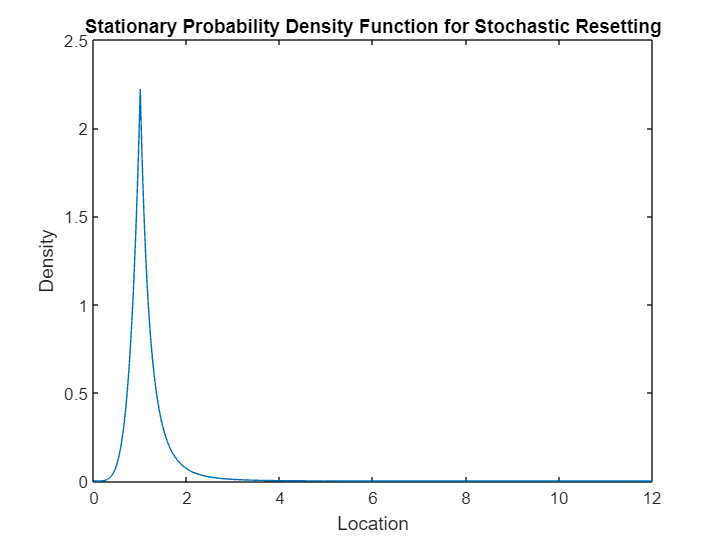

Int = r*int(exp(-r*t)*P0givenxr);
%Pr = exp(-r*t)*P0-Int+subs(Int,t,0); %the integral at 0 does not exist

X= 0:.01:12;
Y= PSS(X,xr,r,mu,sigma);
Y=Y(1:length(X),1);
plot(X,Y)
title("Stationary Probability Density Function for Stochastic Resetting")
xlabel("Location")
ylabel("Density")

% Calculate the Sample Data PDF
% initialize variables
income_points = zeros();
income_time_step = 10000;
number_of_income_paths = 25

number_of_income_paths = 25


%Calculate and store income points
period = 30;
Income_final = zeros(1,n);
pz = r*dt;
for j = 1:n
    Xtemp = Xzero;
    for i = 1:period/dt
        Z = (pz >= rand);
        dW = sqrt(2*dt)*randn;
        Xtemp = Xtemp + (1-Z)*Xtemp*(mu*dt+sigma*dW)+Z*(Xzero-Xtemp);
        
        % Store income at time step income_time_step in income_points variable
        %if j == 1 && i == income_time_step
            %income_points(1,1) = Xtemp;
        %elseif i == income_time_step
            %income_points(1,end+1) = Xtemp;
        %end
    end
    Income_final(j) = Xtemp;
end

h = Income_final(Income_final<12);
[p,x] = hist(h,100); 
%plot(x,p/sum(p*12/100)); %PDF

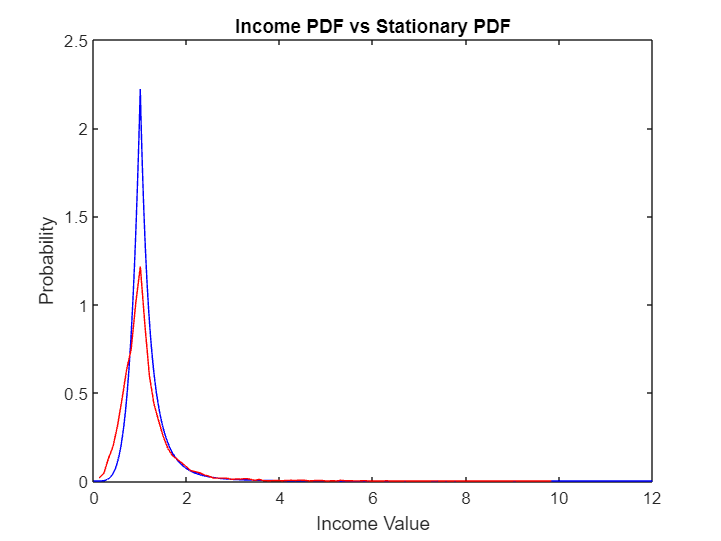



% Plot both PDFs
%test = histcounts(Income_final,12, Normalization = 'pdf');
%plot(test);
hold on
X= 0:.01:12;
Y= PSS(X,xr,r,mu,sigma);
Y=Y(1:length(X),1);
plot(X,Y,'-b')
plot(x,p/sum(p*12/100),'-r'); %PDF
hold off

%Fill this in
title("Income PDF vs Stationary PDF")
xlabel("Income Value")
ylabel("Probability")

# Read in the two files and graph for reference

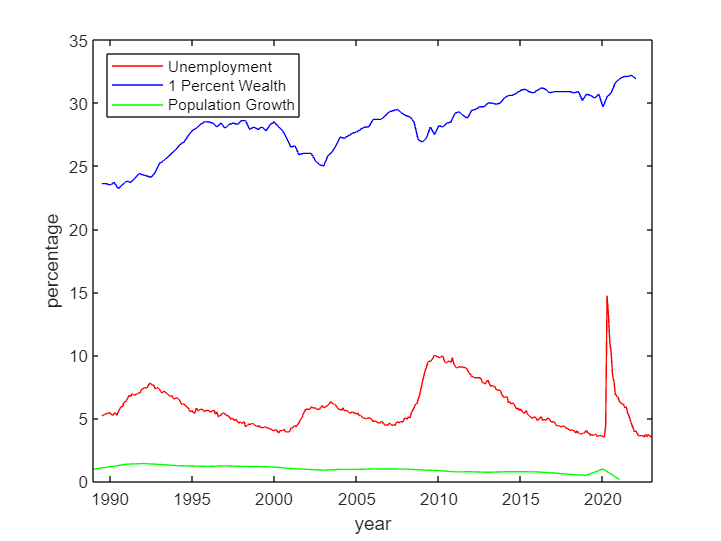

%Top 1% Starts at 1989
%For the sake of comparison we remove 1955-1988 unemployment data from the
%original file

UnemployFile= readtable("/MATLAB Drive/Math 4800/GBM/unemployment89-07.csv");
years = UnemployFile.DATE; % grabs the column labelled'date'
unrate = UnemployFile.UNRATE;
plot(years,unrate, '-r')
hold on;
Top1File = readtable('/MATLAB Drive/Math 4800/GBM/Top1%Share.csv');
years = Top1File.DATE;
top1share = Top1File.WFRBST01134;
plot(years,top1share, '-b')
PopGrowthFile = readtable('/MATLAB Drive/Math 4800/GBM/popgrowth89-07.csv');
years = PopGrowthFile.DATE;
popgrowth = PopGrowthFile.SPPOPGROWUSA;
plot(years,popgrowth, '-g')
legend('Unemployment','1 Percent Wealth','Population Growth', 'Location', 'northwest')
xlabel('year')
ylabel('percentage')

%Unemployment Data for UK and Canada
%need to fix graph data

%opts = detectImportOptions('/MATLAB Drive/Math 4800/GBM/UKUnemploy.xls');
%opts = setvaropts(opts,"DATE",'inputFormat','MM/dd/uuuu');
%UKUnemploy = readtable('UKUnemploy.xls',opts);
%years = UKUnemploy.DATE; % grabs the column labelled'date'
unrate = .01.*UKUnemploy.UNRATE;

Unable to resolve the name 'UKUnemploy.UNRATE'.

plot(years,unrate, '-b')
hold on;

opts = detectImportOptions('CanUnemploy.csv');
opts = setvaropts(opts,"DATE",'inputFormat','MM/dd/uuuu');
CanUnemploy= readtable('CanUnemploy.csv',opts);
unrate = .01.*CanUnemploy.UNRATE;
plot(years,unrate, '-r')
hold on;


title('UK vs Canada')
legend('UK Unemployment','Canada Unemployment', 'Location', 'northwest')
xlabel('year')
ylabel('percentage')

%Need to gather data for top1%
%Best source I have for UK https://www.inet.ox.ac.uk/files/Top_wealth_shares_UK_19Dec2016.pdf
%Page 94
% and https://www.ons.gov.uk/peoplepopulationandcommunity/personalandhouseholdfinances/incomeandwealth/adhocs/008637proportionofaggregatetotalwealthbycomponentheldbytop5andtop1ofhouseholdsgreatbritainjuly2010tojune2016
% I need to merge these to data sets
%currently I have the file UKTestData for Top 1%
%Best source for Canada:

Step 1 

fix resetting rate r at time 0 then find mu and sigma that fit the stationary distribution. (AKA PSS found above)


%SD = SquaredDiff(unrate,top1share); %output should be the best fit mu and sigma at time 0

Build srBM for step 2

 using 1− ˆr(τ )∆t  so that

x(τ ∆t) = x[(τ − 1)∆t][μ +σ √∆tη (τ ∆t)] this is S29 on page 22

eta = normrnd(1,0); %random variable with mean 0 and variance 1
%x(tau*dt) = x((tau+1)t)*(mu+sigma*sqrt(dt)*eta(tau*dt))

Equation *S34 

%xi(t+dt) = xi(t)+xi(t)*(mu(tau)*dt+sigma(tau)*sqrt(dt)*eta(tau*dt))

% The equations based on the paper
syms S M R
Q1 = (sqrt((S^2-2*M)^2+8*R*S^2)+(S^2-2*M))/(2*M^2)

q1 = subs(Q1,[S,m,r],[sigma,mu,r])

Tx0=(Xzero./Xthresh).^q1;
TxR=(X0./Xthresh).^q1;
Tr = (1-Tx0)./(r.*TxR);
a
b
c
d


SD = SquaredDiff(unrate,top1share)

function P = PS(x,xreset,r,sigma,mu)

 %preallocate the vector
    alpha = (-(mu-(sigma^2)/2)+sqrt((mu-(sigma^2)/2)^2+2*r*sigma^2))/(sigma^2);
    c = r.*sigma^2/(alpha.*sigma^2+(mu-(sigma.^2)./2));
    %set P equal to different values of length of x vector
 
    if x>xreset
        P = c.*(x/xreset).^(-alpha-1);
    else
       P =  c*(x/xreset).^(alpha+2.*mu-(sigma.^2)./2 -1);
    end
end

function P = PSS(x,xreset,r,sigma,mu)
P=zeros(length(x)); %preallocate the vector
    alpha = (-(mu-(sigma^2)/2)+sqrt((mu-(sigma^2)/2)^2+2*r*sigma^2))/(sigma^2);
    c = r.*sigma^2/(alpha.*sigma^2+(mu-(sigma.^2)./2));
    %set P equal to different values of length of x vector
  for i=1:(length(x))
     %value of P(i) depends of xr

    if x(i)>xreset
        P(i)=c.*(x(i)./xreset).^(-alpha-1);
    else
       P(i)= c*(x(i)./xreset).^(alpha+2.*mu-(sigma.^2)./2 -1);
    end
  end
end

function SD = SquaredDiff(unrate,top1share)
syms x
unemploy = unrate(1);
t1 = top1share(1);
xreset = 1;
CurrentDiff = 1000;


        for m = 1:1000 
            
            for s = 1:1000
                Sig =s*(1/1000);
                Mu =m*(1/1000);
                %Find X99                             
                % Define p(x) function
               
    target_value = 0.99;
    X99_initial_guess = 1;
    X99 = fminsearch(@(B) error_function(B, target_value, xreset,unemploy, Sig, Mu), X99_initial_guess);
    fprintf('Value of X99: %f\n', X99);
                
                % Compare results to income share data
                
                %redefine as function handle
                Equ= @(x) PS(x,xreset,unemploy,Sig,Mu);
                Broken = @(x) x*Equ;
                diff = t1^2 -(integral(@(x) Broken,X99,Inf)/integral(@(x) Broken,0,Inf))^2;
                if diff<= CurrentDiff %checks if there is a better sig and mu value
                    SD = [Sig, Mu];
                    CurrentDiff = diff;
                end
            end
        end
end
function int_P = int_PS(X99, xreset, r, sigma, mu)
    func = @(x) PS(x, xreset, r, sigma, mu);
    int_P = integral(func, 0, X99);
end

function error_func = error_function(B, target_value, xreset, r, sigma, mu)
    error_func = abs(int_PS(B, xreset, r, sigma, mu) - target_value);
end


function s = share(unem,reset,mu,sigma)
    sum = 0;
    h = 0.01;
    x = 0;
    lsum = 0;
    usum = 0;
    while sum<0.99
       v = h*(PS(x,reset,unem,sigma,mu)+PS(x+h,reset,unem,sigma,mu))/(2*0.9333);
       sum = sum + v;
       lsum = lsum+x*v;
       x = x+h;
       if (x>100000)
        break;
       end
    end
    h=0.1;
    while x<10000
        usum = usum+x*h*PS(x,reset,unem,sigma,mu);
        x=x+h;
    end
    s = usum/(lsum+usum);
end

function [mu, sigma] = match(unem,reset,top1share)
    mu = 1;
    sigma = 1;
    dmu = 0.1;
    dsigma = 0.1;
    s = share(unem,reset,mu,sigma);
    err = abs(top1share-s);
    while err > 0.001
        gradm = (share(unem,reset,mu+dmu,sigma)-s)/dmu;
        grad
    end
end


function f = objectiveFcn(optimInput)
% Example:
% Minimize Rosenbrock's function
% f = 100*(y - x^2)^2 + (1 - x)^2

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
f = 100*(y - x^2)^2 + (1 - x)^2;
end
